Change the temperature here according to your heart's desire

% open the googP_logits.mat file from get_logits folder

introduce_functions;
temperature = 10;


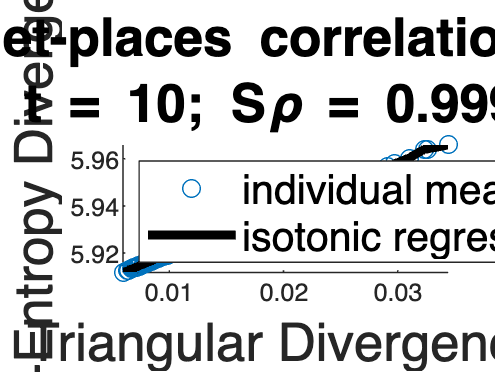


logits = googP_logits(1:1000,:);

%create a vector with first element 1 and the others zero
Y_logit = zeros(1,size(logits,2));
Y_logit(1) = 1;

smData = soft_max(logits,temperature);
smYData = soft_max(Y_logit,temperature);

dists1 = CED(smYData,smData);
dists2 = TRI(smYData,smData);


chart_title1 = strcat("GoogleNet-places"," correlation: CED/TRI");
chart_title2 = strcat("t = ",num2str(temperature));
chart_title = [chart_title1,chart_title2];

shepard_spear(dists1,dists2,chart_title,"Triangular Divergence","Cross-Entropy Divergence");